# 複数競技の統一的モデル：シミュレーション(3)

## 試合中の得点割合から勝率を求める

clear;clc;close all;
N=1000;
totalScoreVals=[150 60 25 3]; %1試合の合計得点
pAVals=0.1:0.02:0.9; %チームAの1試合の得点割合

plotData=[log(pAVals')-log(1-pAVals')];
for totalScore=totalScoreVals
    plotDataCol=[];
    for pAVal=pAVals
        pBVal=1-pAVal;    %チームBの1試合の得点割合
        x=1;
        pa=pAVal*totalScore/N;
        pb=pBVal*totalScore/N;

        for n1=1:N
            x=conv(x,[pb 1-pa-pb pa]);
        end

        plotDataCol=[plotDataCol;1-sum(x(1:N))-x(N+1)/2];
    end
    plotData=[plotData plotDataCol];
end

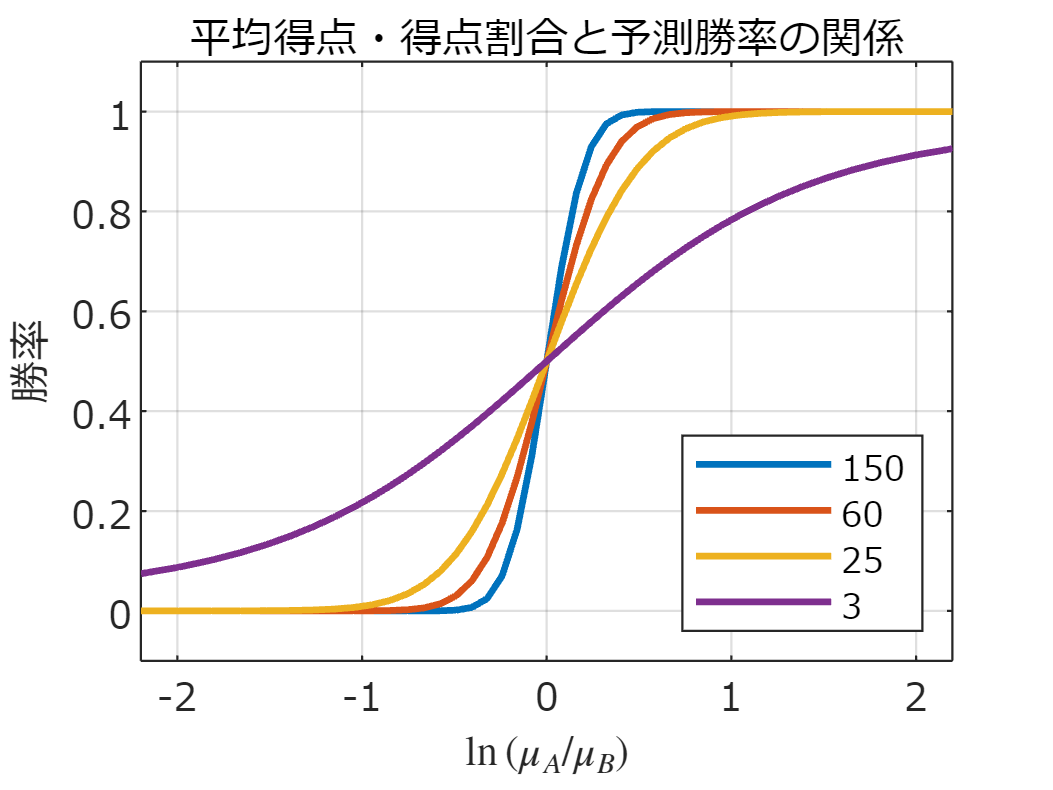

figure
plot(plotData(:,1),plotData(:,2:end),'LineWidth',1.5);
ylim([-0.1 1.1]);
xlim([min(plotData(:,1)) max(plotData(:,1))])
grid on;set(gca,'fontname','メイリオ');hold on;
xlabel('$\ln \left(\mu_A/\mu_B\right)$','Interpreter','latex');
legend(strsplit(num2str(totalScoreVals)),'Location','southeast');
ylabel('勝率');
title('平均得点・得点割合と予測勝率の関係');

exportgraphics(gcf,'fig_unifiedModelSimulation03.pdf');